# Create and Customize Polar Histograms

`polarhistogram` creates a histogram plot in polar coordinates by sorting the input values into equally spaced bins. Specify the values in radians.

### Create Angular Dataset

A polar histogram is best suited for angular data, this case in radians, as it will create bins corresponding in size to the amount of data contained between two angles. So, create a vector of values between $0$ and $2\pi$

theta = [0.1 1.1 5.4 3.4 2.3 4.5 3.2 3.4 5.6 2.3 2.1 3.5 0.6 6.1];

### Basic Polar Histogram

Plotting the vector will sort the data into equally spaced bins for which the arc contains the angles represented by the bins. The magnitude of the bin is plotted radially.

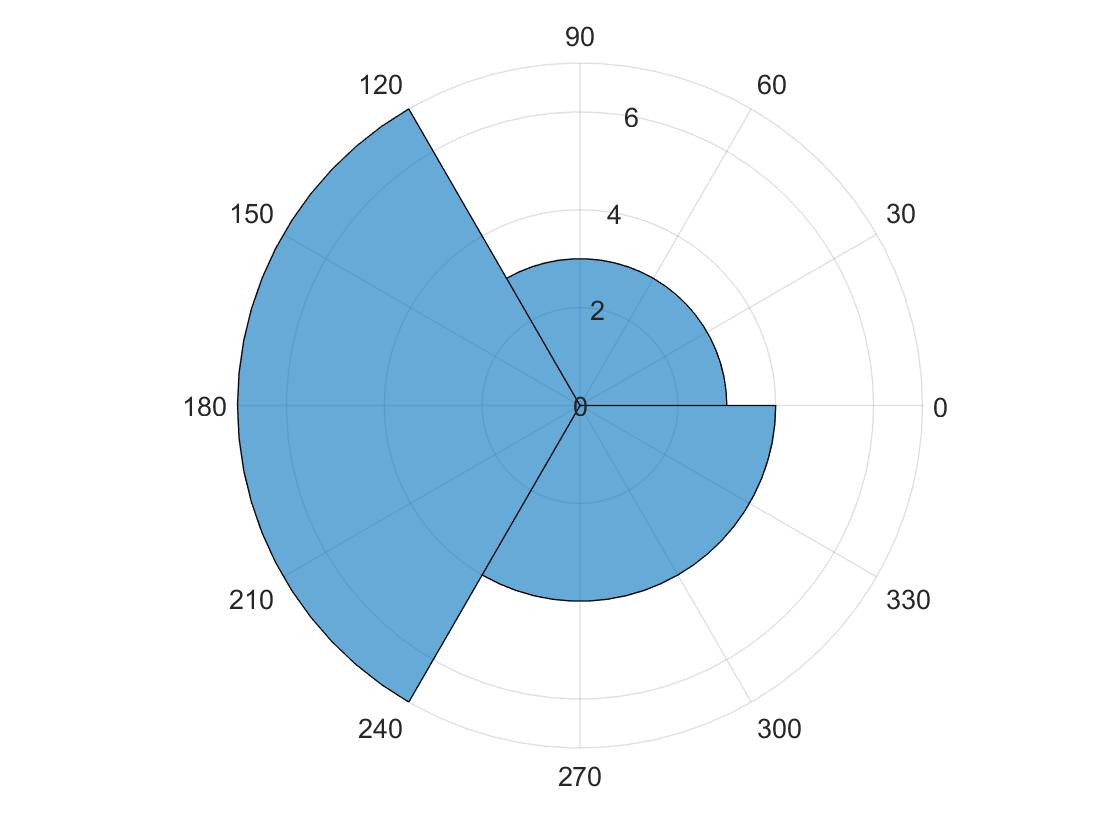

polarhistogram(theta)

## Customizations

### Specify the Number of Bins

If a larger dataset is being plotted with for a specific number of bins, the desired amount of bins can be provided to the `polarhistogram` function call after the data. For example, create a histogram plot from 100,000 values between −$\pi$ and $\pi$, and sort the data into 25 bins.

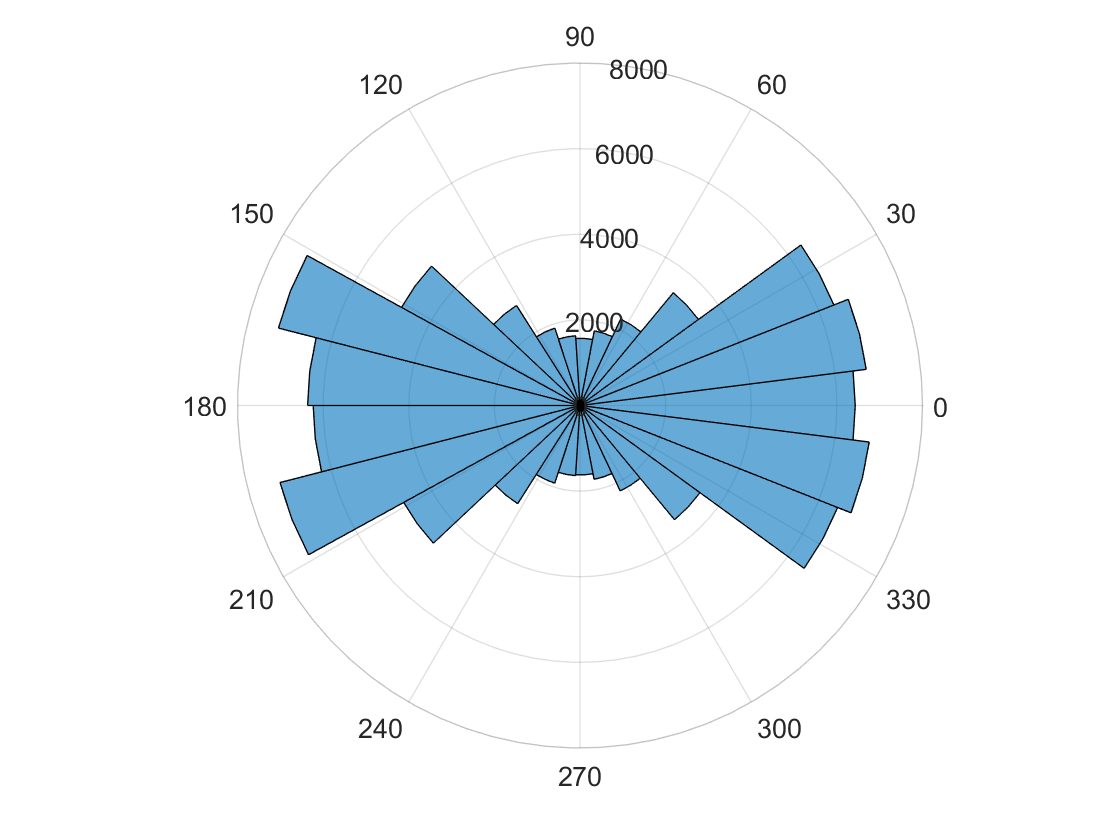

theta = atan2(rand(100000,1)-0.5,2*(rand(100000,1)-0.5)); 
polarhistogram(theta,25);

### Specify Color and Transparency 

The fill color, edge color, and transparency for all the bins can be adjusted using the properties, *FaceColor*,* EdgeColor*, and* FaceAlpha* respectively*. *Setting these properties is done through name-value pair calls following the data to the polarhistogram function. The colors are defined either by color codes or RGB vectors while transparency is defined by a scalar between 0 and 1. Additionally, the edge line thickness can be modified using the* LineWidth *property.

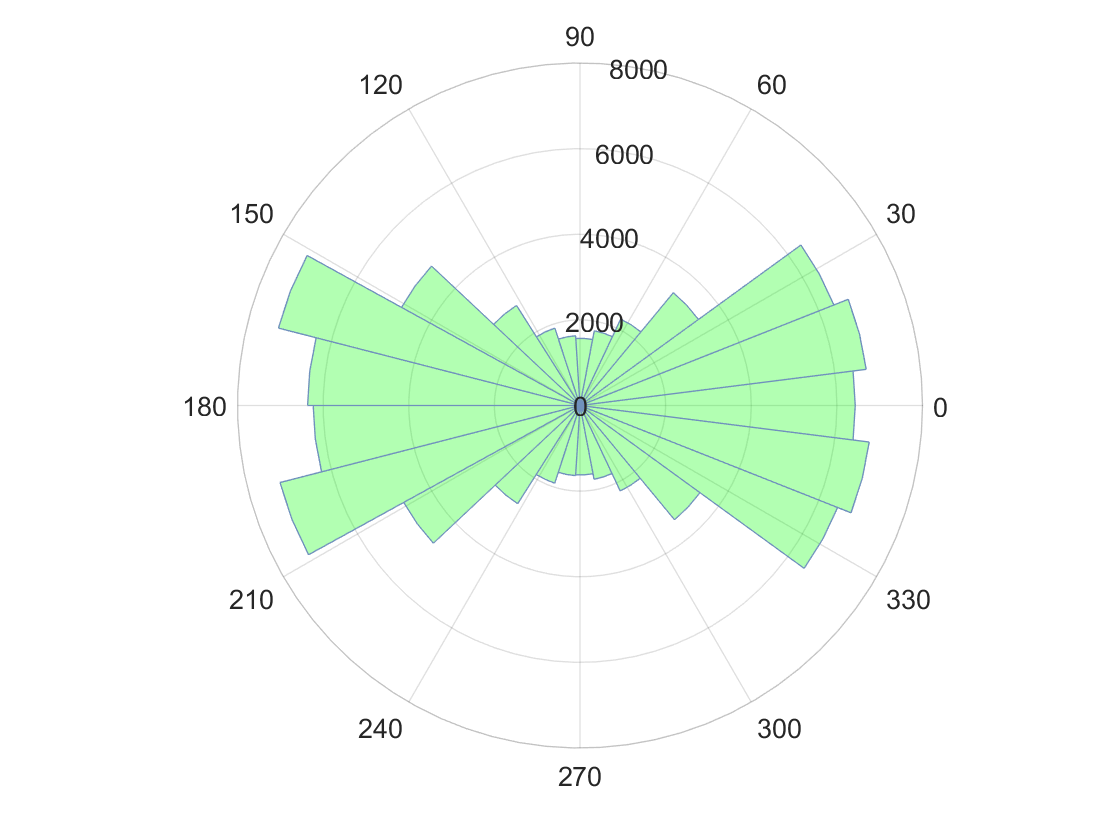

FaceColor = "green";
Transparency = 0.3;
LineWidth = 0.5;
ph = polarhistogram(theta,25,...
    "FaceColor",FaceColor,...                       % Specify the face color
    "EdgeColor",[0.44,0.57,0.74],...                % Specify the edge color using RGB vector
    "FaceAlpha",Transparency,...                    % Specify fill transparency 
    "LineWidth",LineWidth);                         % Specify the edge line width


title('Polar Histogram Chart')

## **Additional Information**

### Get All Polar Histogram Properties

Graphics objects in MATLAB have many properties. To see all the properties of the polar histogram, uncomment the following code

% get(ph)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[Polar Histogram](https://www.mathworks.com/help/matlab/ref/polarhistogram.html)